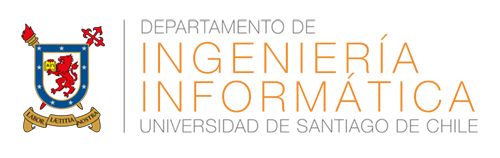

# Laboratorio 1 Señales

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# Señales discretas

La representación de señales discretas se puede realizar utilizando la función stem(eje_x, eje_y) para generar gráficos. Las funciones title, xlabel, ylabel e ylim nos permiten dar formato al gráfico. Las funciones trigonométricas funcionan sobre el arreglo directamente.

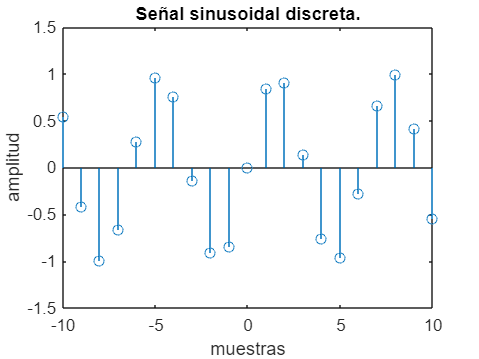

clearvars

n = -10:1:10;        % Utilizamos n para señales discretas
x_n = sin(n);        % (21 muestras). 
figure               % Crea una figura para el gráfico.
stem(n,x_n)
title('Señal sinusoidal discreta.')
xlabel('muestras')   % Etiqueta del eje x.
ylabel('amplitud')   % Etiqueta del eje y.
ylim([-1.5 1.5])     % Límites del eje y.

Para señales de mayor cantidad de muestras, la función plot(eje_x, eje_y) nos entrega un gráfico de líneas entre cada muestra. Ambas señales son discretas, pero utilizamos plot para mejorar la visualización.

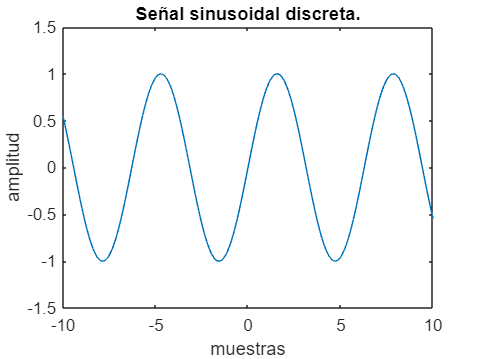

clearvars

n = -10:0.1:10;      % 201 muestras.
x_n = sin(n);
figure
plot(n,x_n)
title('Señal sinusoidal discreta.')
xlabel('muestras')
ylabel('amplitud')
ylim([-1.5 1.5])

# Transformaciones en variable independiente

Desplazamiento de tiempo (shifting):

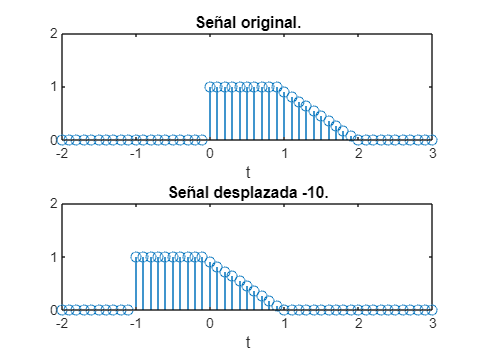

clearvars

t = 0:0.1:5;
T = 10;                         % 10 muestras serán equivalente a 1.
y = zeros(1,length(t));
y(1,1:2*T+1) = 1;               % Señal Figura 1.13 Oppenheim.
y(1,T:2*T+1) = y(1,T:2*T+1)-linspace(0,1,T+2);
t = [-5:0.1:-0.1 t];
y = [zeros(1,50) y];
y_shift = circshift(y,-10);     % Desplaza la señal de manera circular
                                % manteniendo el número de muestras.
figure                          
subplot(2,1,1)                  % Subgráficos de 2 filas 1 columna. 
stem(t,y)
xlim([-2 3])
ylim([0 2])
title('Señal original.')
xlabel('t')
subplot(2,1,2)
stem(t,y_shift)
xlim([-2 3])
ylim([0 2])
title('Señal desplazada -10.')
xlabel('t')

Inversión:

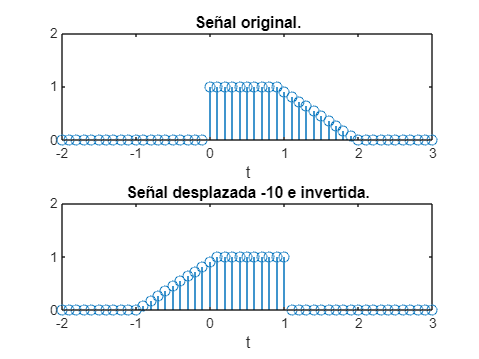

figure
subplot(2,1,1)
stem(t,y)
title('Señal original.')
xlabel('t')
xlim([-2 3])
ylim([0 2])
subplot(2,1,2)
stem(-t,y_shift)                           % -t invierte el gráfico.
title('Señal desplazada -10 e invertida.') % El valor de t no cambia.
xlabel('t')
xlim([-2 3])
ylim([0 2])

Contracción:

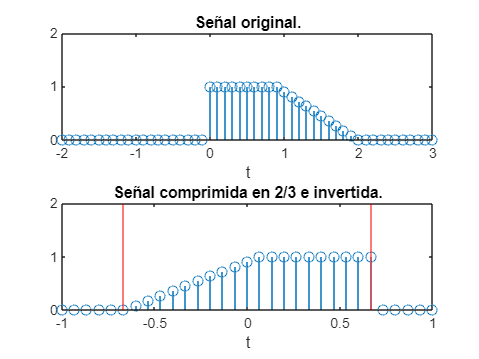

figure
subplot(2,1,1)
stem(t,y)
xlim([-2 3])
ylim([0 2])
title('Señal original.')
xlabel('t')
subplot(2,1,2)
stem(-t*2/3,y_shift)   % Se comprime los valores de t para el gráfico.
xlim([-1 1])           % Los valores de t no cambian.
hold on
xline(-2/3,'-r')       % Línea vertical roja en x = -2/3.
hold on
xline(2/3,'-r')        % Línea vertical roja en x = 2/3.
title('Señal comprimida en 2/3 e invertida.')
xlabel('t')
ylim([0 2])

# Señales periódicas

En Matlab podemos utilizar la función gensig para generar señales periódicas. 

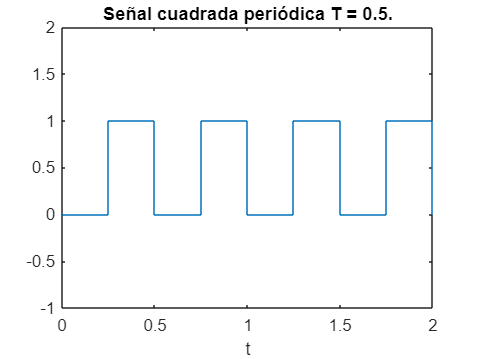

clearvars

T = 0.5;                          % Periodo = T.
Tf = 2;                           % Tf/T periodos en total.
[u0,t] = gensig("square",T,Tf);
figure
stairs(t,u0)
ylim([-1 2])
title('Señal cuadrada periódica T = 0.5.')
xlabel('t')

# Señales par e impar

Podemos generar señales pares es impares a partir de una señal de largo finito.

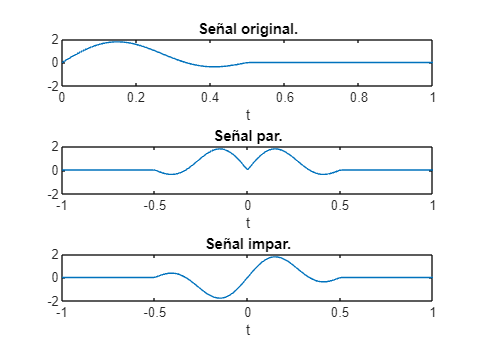

clearvars

N = 100;
t = linspace(0,1,N);
y = sin(2*pi*t)+sin(4*pi*t);
y(N/2+1:end) = 0;              % Señal. Para vectores podemos omitir
figure                         % el primer numero en la indexación.   
subplot(3,1,1)
plot(t,y)
ylim([-2 2])
title('Señal original.')
xlabel('t')

t_s = [-fliplr(t(2:end)) t];   % fliplr invierte la señal de izquierda
y_s = [fliplr(y(2:end)) y];    % a derecha.
subplot(3,1,2)
plot(t_s,y_s)
ylim([-2 2])
title('Señal par.')
xlabel('t')

y_as = [-fliplr(y(2:end)) y];  % Negando el valor de la señal se vuelve
subplot(3,1,3)                 % impar.
plot(t_s,y_as)
ylim([-2 2])
title('Señal impar.')
xlabel('t')

# Señales exponenciales y sinusoidales discretas

Exponenciales:

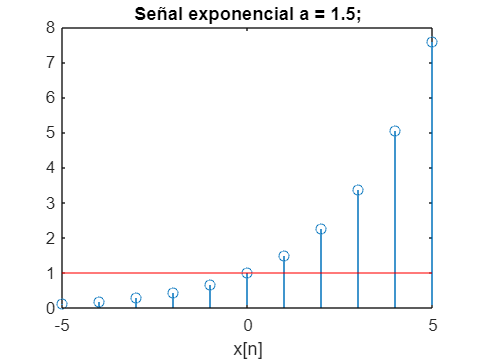

clearvars

n = -5:5;
C = 1;
a = 1.5;
y = C*a.^n;
figure
stem(n,y)
hold on
yline(1,'-r')                         % Línea horizontal en y = 1
title('Señal exponencial a = 1.5;')   % de color rojo.
xlabel('x[n]')

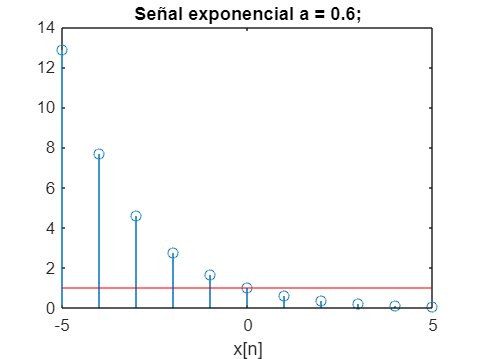


a = 0.6;
y = C*a.^n;
figure
stem(n,y)
hold on
yline(1,'-r')
title('Señal exponencial a = 0.6;')
xlabel('x[n]')

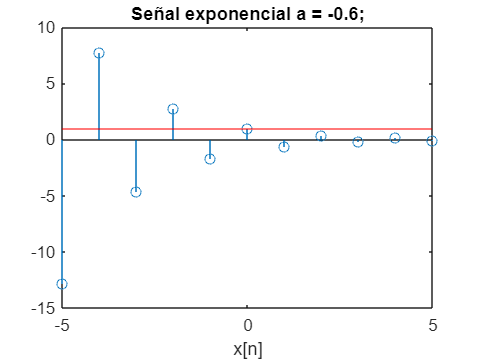


a = -0.6;
y = C*a.^n;
figure
stem(n,y)
hold on
yline(1,'-r')
title('Señal exponencial a = -0.6;')
xlabel('x[n]')

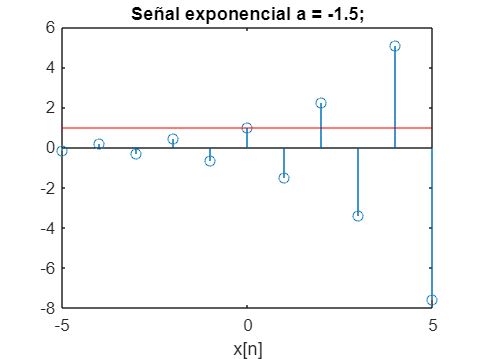


a = -1.5;
y = C*a.^n;
figure
stem(n,y)
hold on
yline(1,'-r')
title('Señal exponencial a = -1.5;')
xlabel('x[n]')

Sinusoidales:

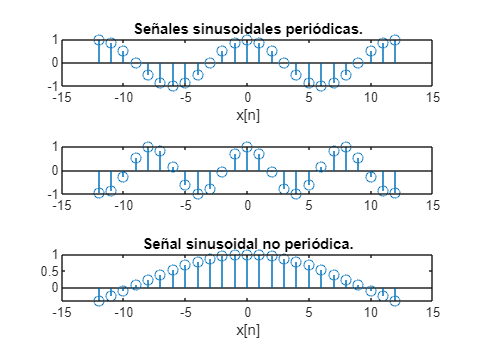

clearvars

n = -12:12;
y = cos(2*pi*n/12);
figure
subplot(3,1,1)
stem(n,y)
title('Señales sinusoidales periódicas.')
xlabel('x[n]')
y = cos(8*pi*n/31);
subplot(3,1,2)
stem(n,y)

y = cos(n/6);                % No periódica.
subplot(3,1,3)
stem(n,y)
title('Señal sinusoidal no periódica.')
xlabel('x[n]')

# Sistemas discreto

## Sistemas estáticos/dinámicos

Ejemplo de sistema estático:


$$${y[n] = a x[n]}$$$


clearvars
disp('Estático')

Estático


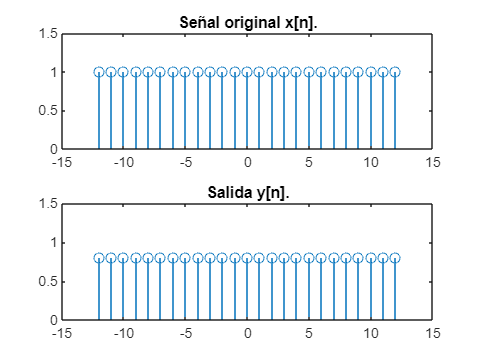


zpv = 12;
a = 0.8;
n = -zpv:zpv;
x_n = ones(1,length(n));
y_n = a*x_n;

figure
subplot(2,1,1)
stem(n,x_n)
ylim([0 1.5])
title('Señal original x[n].')
subplot(2,1,2)
stem(n,y_n)
ylim([0 1.5])
title('Salida y[n].')

Ejemplo de sistema dinámico:


$$${y[n] = \sum_{k=0}^N x[n - k]}$$$


clearvars
disp('Dinámico')

Dinámico


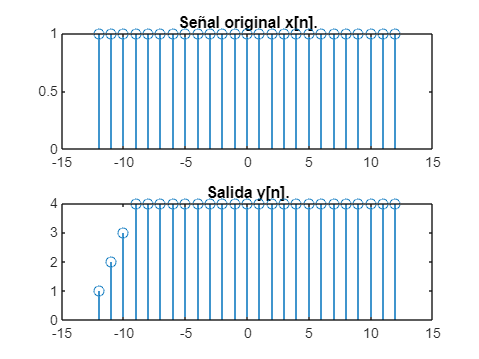


zpv = 12;
n = -zpv:zpv;
N = 3;
x_n = ones(1,length(n));
y_n = zeros(1,length(n));

for i = 1:length(n)
    sum = 0;
    for j = 0:N
        if i-j > 0
            sum = sum + x_n(i-j);
        end
    end
    y_n(1,i) = sum;
end

figure
subplot(2,1,1)
stem(n,x_n)
title('Señal original x[n].')
subplot(2,1,2)
stem(n,y_n)
title('Salida y[n].')

## Sistemas variantes/invariantes en el tiempo

Ejemplo de sistema no variante en el tiempo:


$$${y[n] = a x[n]}$$$


clearvars
disp('No variante en el tiempo')

No variante en el tiempo


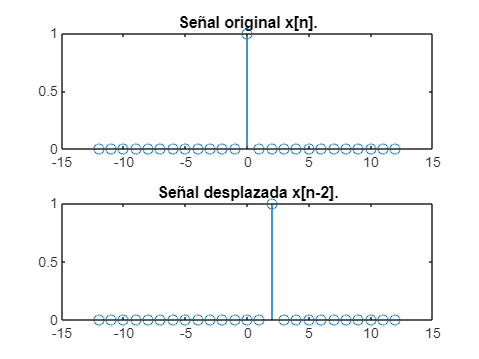


zpv = 12;
a = 0.8;
n = -zpv:zpv;
x_n = zeros(1,length(n));
x_n(zpv+1) = 1;
x_n_2 = circshift(x_n,2);
y_n_a = a*x_n_2;
y_n_b = circshift(a*x_n,2);

figure
subplot(2,1,1)
stem(n,x_n)
title('Señal original x[n].')
subplot(2,1,2)
stem(n,x_n_2)
title('Señal desplazada x[n-2].')

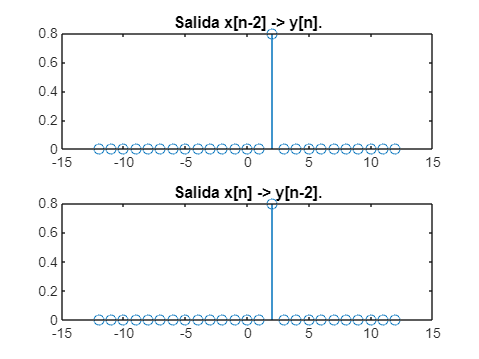


figure
subplot(2,1,1)
stem(n,y_n_a)
title('Salida x[n-2] -> y[n].')
subplot(2,1,2)
stem(n,y_n_b)
title('Salida x[n] -> y[n-2].')

Ejemplo de sistema variante en el tiempo:


$$${y[n] = n x[n]}$$$


clearvars
disp('Variante en el tiempo')

Variante en el tiempo



zpv = 12;
n = -zpv:zpv;
x_n = zeros(1,length(n));
x_n(zpv+1) = 1;
x_n_2 = circshift(x_n,2);
y_n_a = n.*x_n_2;
y_n_b = circshift(n.*x_n,2);

figure
subplot(2,1,1)
stem(n,x_n)
title('Señal original x[n].')
subplot(2,1,2)
stem(n,x_n_2)
title('Señal desplazada x[n-2].')

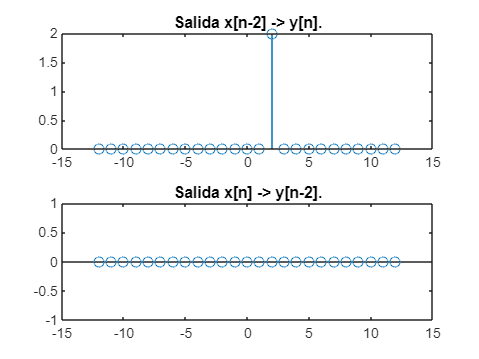


figure
subplot(2,1,1)
stem(n,y_n_a)
title('Salida x[n-2] -> y[n].')
subplot(2,1,2)
stem(n,y_n_b)
title('Salida x[n] -> y[n-2].')

## Linealidad

Para un ejemplo de sistema lineal, podemos probar esta característica de un sistema discreto que desplaza una señal en 3 muestras y la escala en 0.8 con dos señales distintas.


$$${y[n] = 0.8 x[n-3]}$$$


clearvars
disp('Lineal')

Lineal


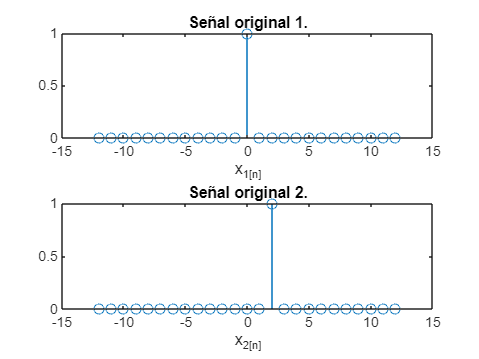


zpv = 12;
n = -zpv:zpv;
x_n_1 = zeros(1,length(n));
x_n_1(zpv+1) = 1;              % Señal impulso unitario.
x_n_2 = circshift(x_n_1,2);    % Señal impulso unitario desplazada en 
                               % 2 muestras.

figure
subplot(2,1,1)
stem(n,x_n_1)
title('Señal original 1.')
xlabel('x_1[n]')
subplot(2,1,2)
stem(n,x_n_2)
title('Señal original 2.')
xlabel('x_2[n]')

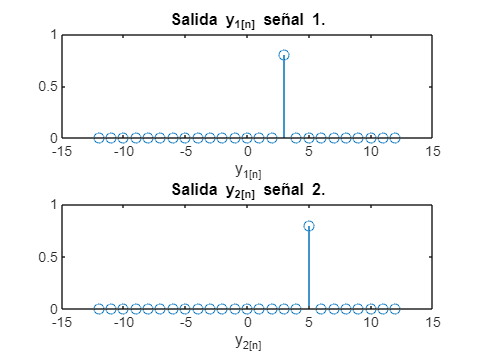


y_1 = 0.8*circshift(x_n_1,3); % Dos salidas a partir de ingresar ambas
y_2 = 0.8*circshift(x_n_2,3); % señales al sistema por separado.
figure
subplot(2,1,1)
stem(n,y_1)
title('Salida y_1[n] señal 1.')
xlabel('y_1[n]')
subplot(2,1,2)
stem(n,y_2)
title('Salida y_2[n] señal 2.')
xlabel('y_2[n]')

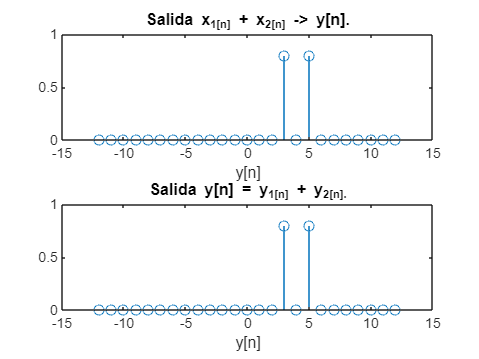


y_12_1 = 0.8*circshift(x_n_1+x_n_2,3); % Salida al ingresar una suma de
y_12_2 = y_1 + y_2;                    % las señales.
figure
subplot(2,1,1)
stem(n,y_12_1)
title('Salida x_1[n] + x_2[n] -> y[n].')
xlabel('y[n]')
subplot(2,1,2)
stem(n,y_12_2)
title('Salida y[n] = y_1[n] + y_2[n].')
xlabel('y[n]')

Ejemplo de sistema no lineal: Distorsión.

clearvars
disp('No Lineal')

No Lineal


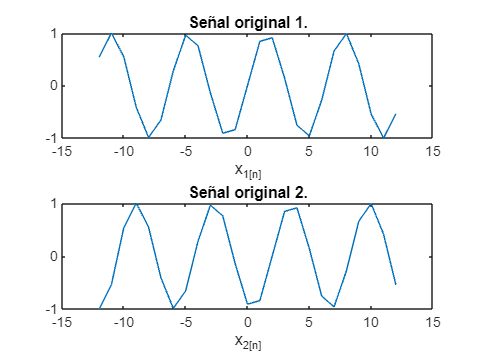


lim = 0.5;
zpv = 12;
n = -zpv:zpv;
x_n_1 = sin(n);
x_n_2 = circshift(x_n_1,2);    % Señal impulso unitario desplazada en 
                               % 2 muestras.
figure
subplot(2,1,1)
plot(n,x_n_1)
ylim([-1 1])
title('Señal original 1.')
xlabel('x_1[n]')
subplot(2,1,2)
plot(n,x_n_2)
ylim([-1 1])
title('Señal original 2.')
xlabel('x_2[n]')

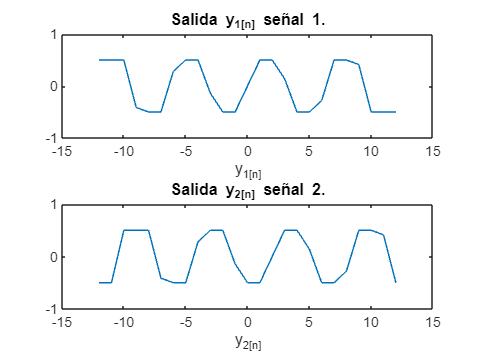


y_1 = x_n_1;                    % Dos salidas a partir de ingresar ambas
y_1(y_1 > lim) = lim;
y_1(y_1 < -lim) = -lim;
y_2 = x_n_2;                    % Dos salidas a partir de ingresar ambas
y_2(y_2 > lim) = lim;
y_2(y_2 < -lim) = -lim;
figure
subplot(2,1,1)
plot(n,y_1)
ylim([-1 1])
title('Salida y_1[n] señal 1.')
xlabel('y_1[n]')
subplot(2,1,2)
plot(n,y_2)
ylim([-1 1])
title('Salida y_2[n] señal 2.')
xlabel('y_2[n]')

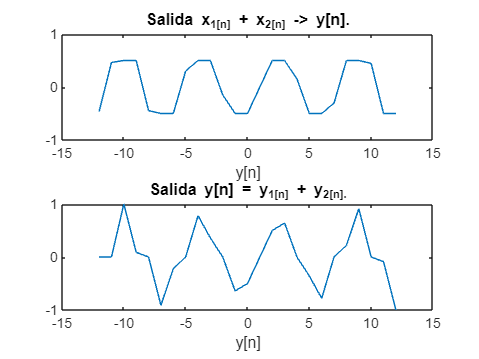


y_12_1 = x_n_1+x_n_2;            % Salida al ingresar una suma de
y_12_1(y_12_1 > lim) = lim;
y_12_1(y_12_1 < -lim) = -lim;
y_12_2 = y_1 + y_2;              % las señales.
figure
subplot(2,1,1)
plot(n,y_12_1)
ylim([-1 1])
title('Salida x_1[n] + x_2[n] -> y[n].')
xlabel('y[n]')
subplot(2,1,2)
plot(n,y_12_2)
ylim([-1 1])
title('Salida y[n] = y_1[n] + y_2[n].')
xlabel('y[n]')

## Sistemas no causales

Ejemplo de sistema no causal: Filtro mediana una dimensión.

clearvars
disp('No causal')

No causal


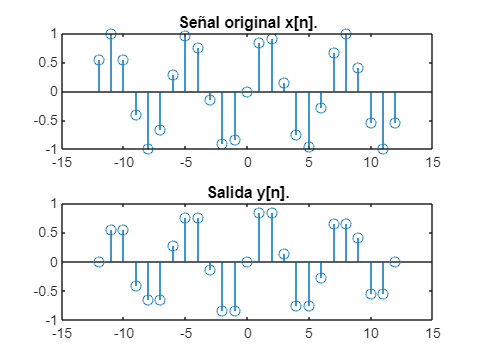


zpv = 12;
n = -zpv:zpv;
N = 1;
x_n = sin(n);
y_n = zeros(1,length(n));

for i = 1:length(n)
    if i-N > 0 && i+N < length(n)+1
        y_n(1,i) = median(x_n(1,i-N:i+N));
    end
end

figure
subplot(2,1,1)
stem(n,x_n)
title('Señal original x[n].')
subplot(2,1,2)
stem(n,y_n)
title('Salida y[n].')

## Sistemas estables/inestables

Ejemplo de sistema estable:


$$${y[n] = \sin(n)}$$$


clearvars
disp('Estable')

Estable


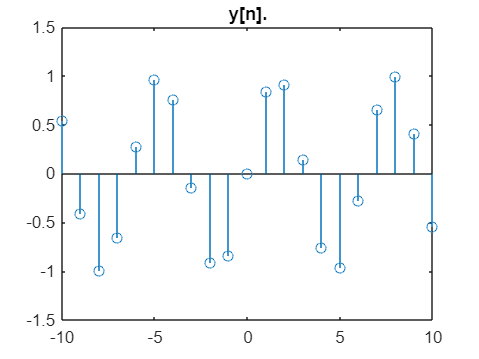


n = -10:1:10;
x_n = sin(n);
figure
stem(n,x_n)
title('y[n].')
ylim([-1.5 1.5])

Ejemplo de sistema inestable:


$$${y[n] = x[n] + 2 y[n-1]}$$$


clearvars
disp('Inestable')

Inestable


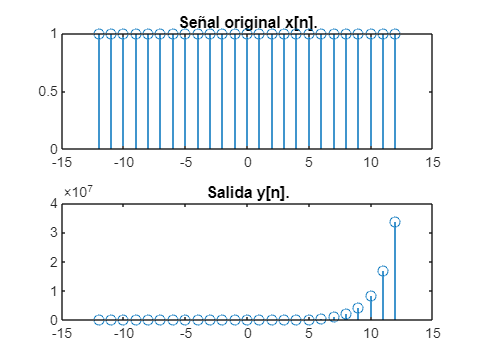


zpv = 12;
n = -zpv:zpv;
x_n = ones(1,length(n));
y_n = ones(1,length(n));

for i = 1:length(n)
    if i-1 > 0
        y_n(1,i) = x_n(1,i) + 2*y_n(1,i-1);
    end
end

figure
subplot(2,1,1)
stem(n,x_n)
title('Señal original x[n].')
subplot(2,1,2)
stem(n,y_n)
title('Salida y[n].')

# Ejercicio

Cree una señal discreta a partir de la función impulso unitario $${\delta[n]}$$ definida como:


$$${\delta[n] = \begin{cases}
  0, & n \neq 0 \\
  1, & n = 0
\end{cases}}$$$


para el intervalo $${-10 \leq n \leq 10}$$. A partir de esta señal $${\delta[n]}$$, cree la señal escalón unitario $${u[n]}$$ **discreta** para el mismo intervalo utilizando la transformación de corrimiento (shifting) vista anteriormente y una iteración con ciclo for.

# Referencias

[1] Oppenheim, A.V. & Willsky, A.S. & Nawab, S.H. (1997). Señales y sistemas (2nd ed.). Prentice Hall.